Exercise 7.1


$$\begin{array}{l}
y_1^{\prime } =-1000y_1 +y_2 ,\;y_1 \left(0\right)=1\\
y_2^{\prime } =1000y_1 -2y_2 ,{\;y}_2 \left(0\right)=0
\end{array}$$


- Show that $y_1$ decays rapidly while $y_2$  decays slowly

- Find the eigenvalues of the associated Jacobian matrix and the stiffness ratio

Q1. Matlab code

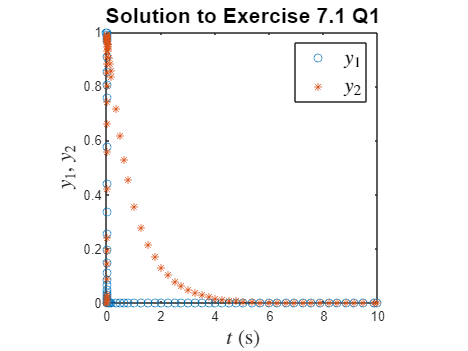

%numerical
tspan=[0 10];
y0=[1 0];

option=odeset('RelTol',1e-6,'AbsTol',1e-6);
[t,y] = ode15s(@odefcn, tspan, y0);

plot(t,y(:,1),'o',t,y(:,2),'*')
axis square
title('Solution to Exercise 7.1 Q1','FontSize',16)
xlabel('$t$ (s)','Interpreter','latex','FontSize',16)
ylabel('$y_1$, $y_2$','Interpreter','latex','FontSize',16)
legend('$y_1$', '$y_2$','Interpreter','latex','FontSize',16)

Q2. The Jacobian matrix is

    
$$J=\left\lbrack \begin{array}{cc}
-1000 & 1\\
1000 & -2
\end{array}\right\rbrack$$


    its eigenvalues are     

lam=eig([-1000 1; 1000 -2])

lam = 1.0e+03 *

   -1.0010
   -0.0010


its stiffness ratio is 

S=max(abs(lam))/min(abs(lam))

S = 1.0020e+03

function dydt=odefcn(t,y)
    dydt=zeros(2,1);
    dydt(1) = -1000*y(1)+y(2);
    dydt(2) = 1000*y(1)-2*y(2);
end